# Diseño de un sistema regulador con observador de estados de orden mínimo

% Ejemplo seccion 10-6 Texto Ogata. Diseño de sistemas reguladores con
% observadores
clear
close all
A = [0 1 0;0 0 1;0 -24 -10]

A =      0     1     0
     0     0     1
     0   -24   -10


B = [0;0;1]

B =      0
     0
     1


C = [20 10 0]

C =     20    10     0


J = [-1+1i*2 -1-1i*2 -5]

J =   -1.0000 + 2.0000i  -1.0000 - 2.0000i  -5.0000 + 0.0000i


sys_ol=ss(A,B,C,0);

## Prueba de controlabilidad

sys_ord=order(sys_ol)

sys_ord = 3

rank_sys=rank(ctrb(A,B))

rank_sys = 3

det(ctrb(A,B))

ans = -1

## Prueba de observabilidad

rank_sys=rank(obsv(sys_ol))

rank_sys = 3

det_sys=det(obsv(sys_ol))

det_sys = 1.6000e+04

## Obtención de la matriz de realimentación de los estados K

K = acker(A,B,J)

K =     25    -9    -3


% Obtaining the observer gain matrix Ke
% Ver ecuaciones 10-81 y 10-82
Aaa = 0; Aab = [1 0]; Aba = [0;0]; Abb = [0 1;-24 -10]

Abb =      0     1
   -24   -10


Ba = 0; Bb = [10;-80];

#### Polos deseados del observador

L = [-10 -10]

L =    -10   -10


## Obtención de la matriz de ganancias Ke para el observador

Ke = acker(Abb',Aab',L)'

Ke =     10
   -24


## Obtencion de la función de transferencia del controlador-observador

Ka=K(1);
Kb=K(2:3);
Ahat = Abb - Ke*Aab;
Bhat = Ahat*Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
% Matrices que definen las ecuaciones 10-106 y 10-107
Atilde = Ahat - Fhat*Kb;
Btilde = Bhat - Fhat*(Ka + Kb*Ke);
Ctilde = -Kb;
Dtilde = -(Ka + Kb*Ke);
% Ecuacion 10-109

### Con la función ss2tf de MATLAB

[num,den] = ss2tf(Atilde, Btilde, -Ctilde, -Dtilde)

num = 1.0e+03 *

    0.0070    0.5360    2.5000


den = 1.0e+03 *

    0.0010    0.1700    2.3200


Gcobs1=tf(num,den)

Gcobs1 =
 
  7 s^2 + 536 s + 2500
  --------------------
   s^2 + 170 s + 2320
 
Continuous-time transfer function.
Model Properties


pole(Gcobs1)

ans =  -155.0357
  -14.9643


### En forma simbólica

syms s
% Ecuacion 10-108
sys1=-(Ctilde*inv(s*eye(size(Atilde,1))-Atilde)*Btilde+Dtilde);
Gcobss=simplify(sys1)

$$Gcobss = \frac{7\,s^{2}+536\,s+2500}{s^{2}+170\,s+2320}$$

#### Observación: el sistema es estable en lazo abierto

## Cálculo de la ecuación característica 

### Mediante MATLAB

[num1,den1] = ss2tf(A-B*K,eye(3),eye(3),eye(3),1);
[num2,den2] = ss2tf(Abb-Ke*Aab,eye(2),eye(2),eye(2),1);
charact_eq = conv(den1,den2)

charact_eq = 1.0e+03 *

    0.0010    0.0270    0.2550    1.0250    2.0000    2.5000


roots(charact_eq)

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


### En forma simbólica

syms s
charact_eqs=det(s*eye(size(A,1))-A+B*K)*det(s*eye(size(Abb,1))-Abb+Ke*Aab)

$$charact\_eqs = {\left(s+10\right)}^{2}\,\left(s^{3}+7\,s^{2}+15\,s+25\right)$$

roots(conv([1 20 100],[1 7 15 25]))

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


#### Observación: el sistema es estable en lazo cerrado

## Segunda prueba:

### Modificando  los polos deseados para el observador de orden mínimo 

L = [-4.5 -4.5]

L =    -4.5000   -4.5000


Ke = acker(Abb',Aab',L)'

Ke =    -1.0000
    6.2500


Ahat = Abb - Ke*Aab;
Bhat = Ahat*Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
% Matrices que definen las ecuaciones 10-106 y 10-107
Atilde = Ahat - Fhat*Kb;
Btilde = Bhat - Fhat*(Ka + Kb*Ke);
Ctilde = -Kb;
Dtilde = -(Ka + Kb*Ke);

## Obtencion de la función de transferencia del controlador-observador

[num,den] = ss2tf(Atilde, Btilde, -Ctilde, -Dtilde)

num =    15.2500  186.7500  506.2500


den =     1.0000  159.0000  507.7500


Gcobs2=tf(num,den)

Gcobs2 =
 
  15.25 s^2 + 186.8 s + 506.3
  ---------------------------
      s^2 + 159 s + 507.7
 
Continuous-time transfer function.
Model Properties


pole(Gcobs2)

ans =  -155.7398
   -3.2602


## Obtención de la respuesta del sistema a condiciones iniciales

% Ecuaciones 10-110 y 10-111 (10-94)
AA = [A-B*K B*Kb; zeros(2,3) Abb-Ke*Aab]

AA =          0    1.0000         0         0         0
         0         0    1.0000         0         0
  -25.0000  -15.0000   -7.0000   -9.0000   -3.0000
         0         0         0    1.0000    1.0000
         0         0         0  -30.2500  -10.0000


sys = ss(AA,eye(5),eye(5),eye(5));
t = 0:0.01:8;
x0=[1;0;0;1;0]   % vector de condiciones iniciales

x0 =      1
     0
     0
     1
     0


x = initial(sys,x0,t)

x =     1.0000         0         0    1.0000         0
    1.0000   -0.0016   -0.3244    1.0086   -0.2892
    1.0000   -0.0064   -0.6190    1.0145   -0.5529
    0.9999   -0.0139   -0.8859    1.0179   -0.7929
    0.9997   -0.0240   -1.1270    1.0190   -1.0107
    0.9994   -0.0364   -1.3441    1.0181   -1.2078
    0.9989   -0.0508   -1.5389    1.0153   -1.3855
    0.9983   -0.0671   -1.7130    1.0108   -1.5453
    0.9976   -0.0850   -1.8678    1.0047   -1.6884
    0.9966   -0.1044   -2.0048    0.9971   -1.8158


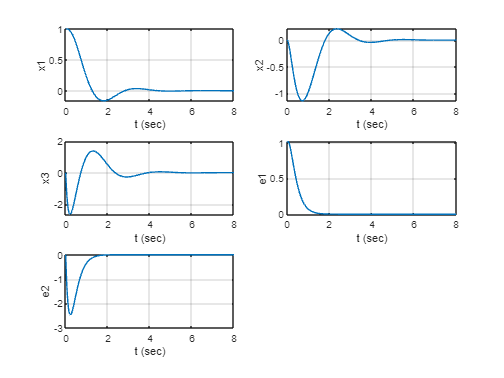

x1 = [1 0 0 0 0]*x';
x2 = [0 1 0 0 0]*x';
x3 = [0 0 1 0 0]*x';
e1 = [0 0 0 1 0]*x';
e2 = [0 0 0 0 1]*x';
figure(1000)
subplot(3,2,1); plot(t,x1); grid
xlabel ('t (sec)'); ylabel('x1')
subplot(3,2,2); plot(t,x2); grid
xlabel ('t (sec)'); ylabel('x2')
subplot(3,2,3); plot(t,x3); grid
xlabel ('t (sec)'); ylabel('x3')
subplot(3,2,4); plot(t,e1); grid
xlabel('t (sec)'); ylabel('e1')
subplot(3,2,5); plot(t,e2); grid
xlabel('t (sec)'); ylabel('e2')

## Diagramas del Bode del sistema regulador diseñado

numol=10*[1 2];
denol=conv([1 4 0],[1 6]);
Gsol=tf(numol,denol)

Gsol =
 
       10 s + 20
  -------------------
  s^3 + 10 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


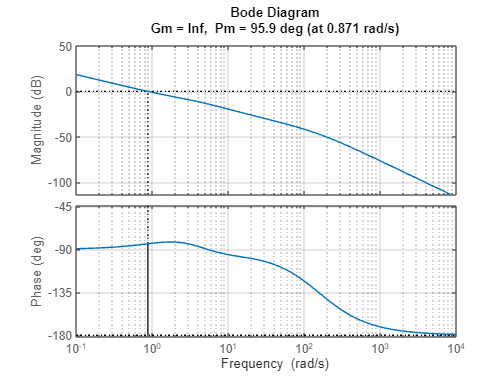

figure(1)
margin(Gsol*Gcobs2)
grid

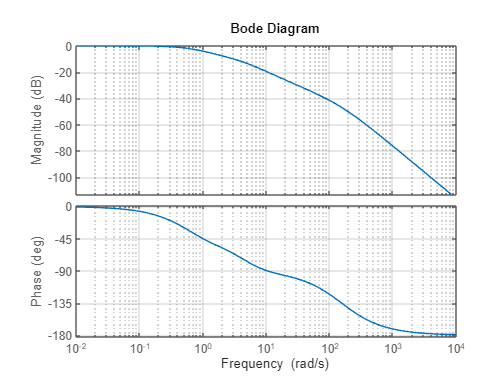

figure(2)
bode(feedback(Gsol*Gcobs2,1))
grid

## Root Locus del sistema regulador con polos del observador en s=-10 y s=-10

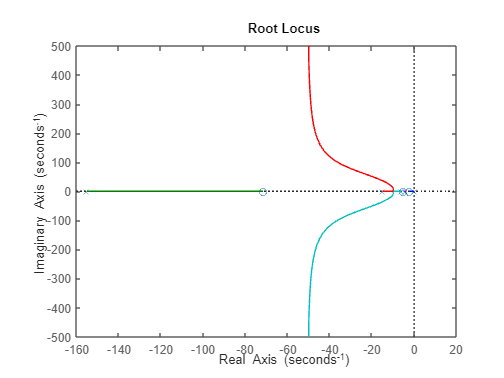

figure(3)
rlocus(Gsol*Gcobs1)

Gsol*Gcobs1

ans =
 
         70 s^3 + 5500 s^2 + 3.572e04 s + 5e04
  ----------------------------------------------------
  s^5 + 180 s^4 + 4044 s^3 + 2.728e04 s^2 + 5.568e04 s
 
Continuous-time transfer function.
Model Properties


## Root Locus del sistema regulador con polos del observador en s=-4.5 y s=-4.5

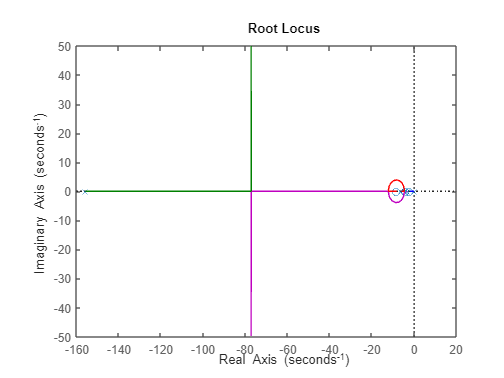

figure(4)
rlocus(Gsol*Gcobs2)

Gsol*Gcobs2

ans =
 
      152.5 s^3 + 2173 s^2 + 8798 s + 1.013e04
  ------------------------------------------------
  s^5 + 169 s^4 + 2122 s^3 + 8893 s^2 + 1.219e04 s
 
Continuous-time transfer function.
Model Properties
